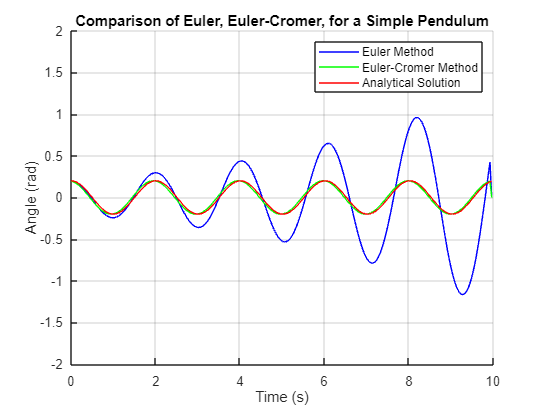

% Declare Constants
g = 9.81;  % acceleration due to gravity 
length = 1; % length of the pendulum 
time_step = 0.04; % time step 
total_time = 10;  % total simulation time 
num_steps = total_time / time_step; % number of time steps

theta0 = 0.2; % initial angle (rad)
phi = 0; % phase constant

% Initial conditions for Euler
theta_euler = theta0;  % initial angle (rad)
omega_euler = 0.0;  % initial angular velocity (rad/s)

% Initial conditions for Euler-Cromer
theta_euler_cromer = theta0;  % initial angle (rad)
omega_euler_cromer = 0.0;  % initial angular velocity (rad/s)

% Preallocate arrays for efficiency
theta_values_euler = zeros(1, num_steps);
omega_values_euler = zeros(1, num_steps);
theta_values_euler_cromer = zeros(1, num_steps);
omega_values_euler_cromer = zeros(1, num_steps);
time_values = 0:time_step:(total_time - time_step); % time array

% Simulation using Euler's method
for i = 1:(num_steps - 1)
    % Calculate the new values using Euler's method
    alpha = -(g / length) * sin(theta_euler);  % angular acceleration (rad/s^2)
    theta_euler = theta_euler + omega_euler * time_step;   % update angle using old omega
    omega_euler = omega_euler + alpha * time_step;   % update angular velocity
    
    % Store the values
    theta_values_euler(i) = theta_euler;
    omega_values_euler(i) = omega_euler;
end

% Simulation using Euler-Cromer method
for i = 1:(num_steps - 1)
    % Update angular velocity
    omega_euler_cromer = omega_euler_cromer - (g / length) * sin(theta_euler_cromer) * time_step;
   
    % Update angle using new angular velocity
    theta_euler_cromer = theta_euler_cromer + omega_euler_cromer * time_step;
    
    % Store the values
    theta_values_euler_cromer(i) = theta_euler_cromer;
    omega_values_euler_cromer(i) = omega_euler_cromer;
end

% The analytical solution
omega_natural = sqrt(g / length); % Natural frequency of the pendulum
theta_analytical = theta0 * cos(omega_natural * time_values + phi); % Analytical solution for theta as a function of time

% Plotting
figure;
hold on; % Hold on to plot multiple datasets on the same figure
plot(time_values, theta_values_euler, 'b-', 'DisplayName', 'Euler Method');
plot(time_values, theta_values_euler_cromer, 'g-', 'DisplayName', 'Euler-Cromer Method');
plot(time_values, theta_analytical, 'r-', 'DisplayName', 'Analytical Solution');
xlabel('Time (s)');
ylabel('Angle (rad)');
title('Comparison of Euler, Euler-Cromer, for a Simple Pendulum');
ylim([-2, 2]);
legend show;
grid on;
hold off; % Release the figure for further plotting